%---------------------------------------------------------
% Ecuaciones de distintos tipos de señales
% Navil Pineda Rugerio
% Inteligencia Artificial
% 5to Semestre
%---------------------------------------------------------
clc

# Funciones

Función de,delta de Dirac

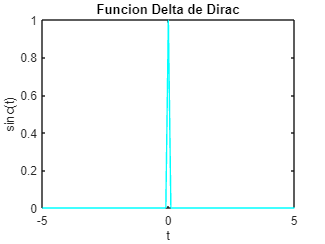

t = -5:0.1:5;

dirac_t = zeros(size(t));

for i = 1:length(t)
    dirac_t(i) = dirac(t(i));
end

plot(t,dirac_t, 'c'), xlabel('t'), ylabel('sinc(t)'), title('Funcion Delta de Dirac');

Función Triangular Unidad

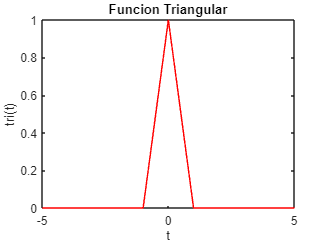

tri_t = zeros(size(t));
for i = 1:length(t)
    tri_t(i) = tri(t(i));
end

plot(t,tri_t, 'r'), xlabel('t'), ylabel('tri(t)'), title('Funcion Triangular');

Función Rampa Unidad

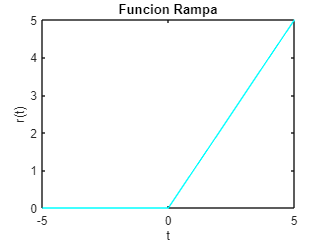

r_t = zeros(size(t));
for i = 1:length(t)
    r_t(i) = r(t(i));
end

plot(t,r_t, 'c'), xlabel('t'), ylabel('r(t)'), title('Funcion Rampa');

Función Pulso Unidad

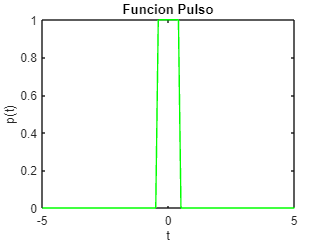

p_t = zeros(size(t));
for i = 1:length(t)
    p_t(i) = p(t(i));
end

plot(t,p_t, 'g'), xlabel('t'), ylabel('p(t)'), title('Funcion Pulso');

Función Escalon Unidad

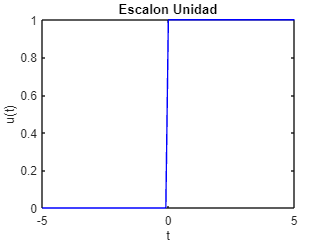

u_t = zeros(size(t));
for i = 1:length(t)
    u_t(i) = u(t(i));
end

plot(t,u_t, 'b'), xlabel('t'), ylabel('u(t)'), title('Escalon Unidad');

Función Sinc

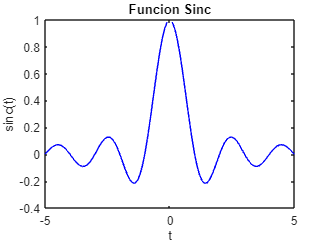

sinc_t = zeros(size(t));
for i = 1:length(t)
    sinc_t(i) = sinc(t(i));
end

plot(t,sinc_t, 'b'), xlabel('t'), ylabel('sinc(t)'), title('Funcion Sinc');

# Transformaciones

Transformaciones a Dirac

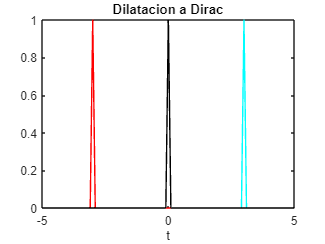

des_d = retraso(@dirac, 3, t);
des_i = adelanto(@dirac, 3, t);
ref_t = reflexion(@dirac,t);
comp_t = compresion(@dirac, t);
dil_t = dilatacion(@dirac, t);
plot(t,des_d, 'c'), xlabel('t'), title('Retraso a Dirac');
hold on;
plot(t,des_i, 'r'), xlabel('t'), title('Adelanto a Dirac');
plot(t,ref_t, 'g'), xlabel('t'), title('Reflexion a Dirac');
plot(t,comp_t, 'b'), xlabel('t'), title('Compresion a Dirac');
plot(t,dil_t, 'k'), xlabel('t'), title('Dilatacion a Dirac');
hold off;

Transformaciones a Triangular

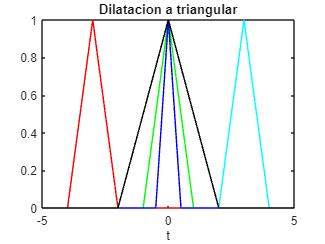

des_d = retraso(@tri, 3, t);
des_i = adelanto(@tri, 3, t);
ref_t = reflexion(@tri,t);
comp_t = compresion(@tri, t);
dil_t = dilatacion(@tri, t);
plot(t,des_d, 'c'), xlabel('t'), title('Retraso a triangular');
hold on;
plot(t,des_i, 'r'), xlabel('t'), title('Adelanto a triangular');
plot(t,ref_t, 'g'), xlabel('t'), title('Reflexion a triangular');
plot(t,comp_t, 'b'), xlabel('t'), title('Compresion a triangular');
plot(t,dil_t, 'k'), xlabel('t'), title('Dilatacion a triangular');
hold off;

Transformaciones a Rampa

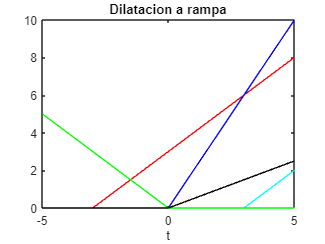

des_d = retraso(@r, 3, t);
des_i = adelanto(@r, 3, t);
ref_t = reflexion(@r,t);
comp_t = compresion(@r, t);
dil_t = dilatacion(@r, t);
plot(t,des_d, 'c'), xlabel('t'), title('Retraso a rampa');
hold on;
plot(t,des_i, 'r'), xlabel('t'), title('Adelanto a rampa');
plot(t,ref_t, 'g'), xlabel('t'), title('Reflexion a rampa');
plot(t,comp_t, 'b'), xlabel('t'), title('Compresion a rampa');
plot(t,dil_t, 'k'), xlabel('t'), title('Dilatacion a rampa');
hold off;

Transformaciones a Pulso

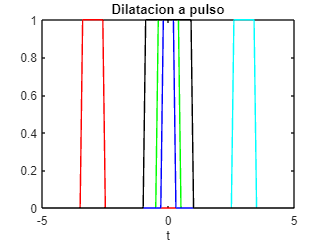

des_d = retraso(@p, 3, t);
des_i = adelanto(@p, 3, t);
ref_t = reflexion(@p,t);
comp_t = compresion(@p, t);
dil_t = dilatacion(@p, t);
plot(t,des_d, 'c'), xlabel('t'), title('Retraso a pulso');
hold on;
plot(t,des_i, 'r'), xlabel('t'), title('Adelanto a pulso');
plot(t,ref_t, 'g'), xlabel('t'), title('Reflexion a rampa');
plot(t,comp_t, 'b'), xlabel('t'), title('Compresion a pulso');
plot(t,dil_t, 'k'), xlabel('t'), title('Dilatacion a pulso');
hold off;

Transformaciones a Escalón

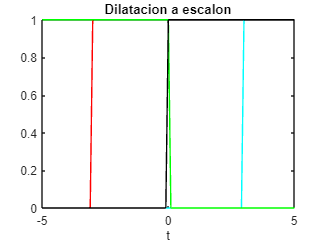

des_d = retraso(@u, 3, t);
des_i = adelanto(@u, 3, t);
ref_t = reflexion(@u,t);
comp_t = compresion(@u, t);
dil_t = dilatacion(@u, t);
plot(t,des_d, 'c'), xlabel('t'), title('Retraso a escalon');
hold on;
plot(t,des_i, 'r'), xlabel('t'), title('Adelanto a escalon');
plot(t,ref_t, 'g'), xlabel('t'), title('Reflexion a escalon');
plot(t,comp_t, 'b'), xlabel('t'), title('Compresion a escalon');
plot(t,dil_t, 'k'), xlabel('t'), title('Dilatacion a escalon');
hold off;

Transformaciones a Sinc

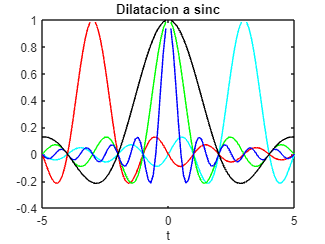

des_d = retraso(@sinc, 3, t);
des_i = adelanto(@sinc, 3, t);
ref_t = reflexion(@sinc,t);
comp_t = compresion(@sinc, t);
dil_t = dilatacion(@sinc, t);
plot(t,des_d, 'c'), xlabel('t'), title('Retraso a sinc');
hold on;
plot(t,des_i, 'r'), xlabel('t'), title('Adelanto a sinc');
plot(t,ref_t, 'g'), xlabel('t'), title('Reflexion a sinc');
plot(t,comp_t, 'b'), xlabel('t'), title('Compresion a sinc');
plot(t,dil_t, 'k'), xlabel('t'), title('Dilatacion a sinc');
hold off;

# Operaciones con señales.

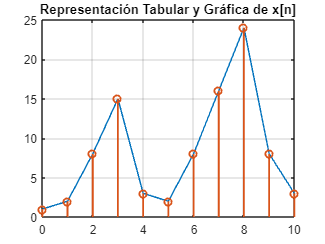

% Primera señal
x = [1,2,8,15,3,2,8,16,24,8,3];
% Segunda señal
y =[15,2,5,3,3,8,2,1,4,2,7];

% Arreglo de valores de 0 a N para evaluar graficar la señal
n = 0:length(x)-1;

% Representación gráfica.
plot(n, x);
hold on;
% Representación tabular
stem(n, x, 'Marker', 'o', 'LineWidth', 1.5);
title('Representación Tabular y Gráfica de x[n]');
grid on;
hold off;

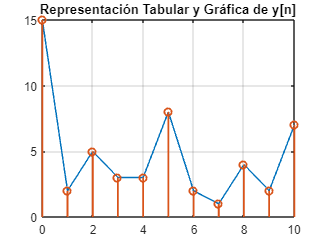


% Representación gráfica.
plot(n, y);
hold on;
% Representación tabular
stem(n, y, 'Marker', 'o', 'LineWidth', 1.5);
title('Representación Tabular y Gráfica de y[n]');
grid on;
hold off;

Suma de señales.

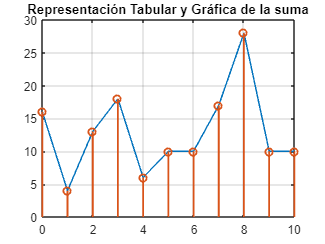

suma = x + y;
% Representación gráfica.
plot(n, suma);
hold on;
% Representación tabular
stem(n, suma, 'Marker', 'o', 'LineWidth', 1.5);
title('Representación Tabular y Gráfica de la suma');
grid on;
hold off;

Multiplicación de señales.

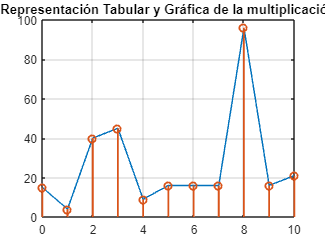

mult = x .* y;
% Representación gráfica.
plot(n, mult);
hold on;
% Representación tabular
stem(n, mult, 'Marker', 'o', 'LineWidth', 1.5);
title('Representación Tabular y Gráfica de la multiplicación');
grid on;
hold off;

# Funciones

function res = dirac(t)
    if t ~= 0
        res = 0;
    else
        res = 1;
    end
end
% res = dirac(t)

% Funcion escalon
function res = u(t)
    if t < 0
        res = 0;
    else
        res = 1;
    end
end

% Funcion rampa
function res = r(t)
    if t > 0
        res = t * u(t);
    else
        res = 0;
    end
end

% Funcion triangular
function res = tri(t)
    if t > (-1) & t < 1
        res = r(t+1) - 2*r(t) + r(t-1);
    else
        res = 0;
    end
end

% Función pulso
function res = p(t)
    if t > (-1/2) & t < (1/2)
        res = u(t+(1/2)) - u(t-(1/2));
    else
        res = 0;
    end
end

% Funcion sinc
function res = sinc(t)
    res = sin(pi*t) / (pi*t);
end

# Transformaciones

Dezplazamiento a la derecha en el tiempo

function res_t = retraso(funcion, f_des, t)
    res_t = zeros(size(t));
    for i = 1:length(t)
        val = t(i)-f_des;
        res_t(i) = funcion(val);
    end
end

Desplazamiento a la izquierda en el tiempo

function ad_t = adelanto(funcion, f_des, t)
    ad_t = zeros(size(t));
    for i = 1:length(t)
        val = t(i)+f_des;
        ad_t(i) = funcion(val);
    end
end

Reflexión: inversión en el tiempo

function inv_t = reflexion(funcion, t)
    inv_t = zeros(size(t));
    for i = 1:length(t)
        val = t(i) * (-1);
        inv_t(i) = funcion(val);
        %inv_t = inv_t * (-1);
    end
end

Cambios lineales de escala en variable independiente: compresión

function comp_t = compresion(funcion, t)
    comp_t = zeros(size(t));
    for i = 1:length(t)
        val = t(i) * 2;
        comp_t(i) = funcion(val);
    end
end

Cambios lineales de escala en variable independiente: dilatación

function dil_t = dilatacion(funcion, t)
    dil_t = zeros(size(t));
    for i = 1:length(t)
        val = t(i) / 2;
        dil_t(i) = funcion(val);
    end
end